# Module 2 Project 1 Owen Rogg

%{
Made by Owen Rogg, April 1st-6th 2026 
Module 2 project 1, project bank 2 project #7
Robot Motion in One Dimension

Objective is to simulate robot motion with velocity
limits and acceleration constraints.

Tasks:
Implement motion update logic
Detect stopping or reversing events
Position/velocity plots
Motion analysis

Preliminary thoughts for implementation

the projects in the second bank are much more vague and leave a lot of
the specifics up to interpretation. I am thinking maybe i make some tables
with chosen velocity and time values and use those charts
to create graphs, showing the position, acceleration, and determining if
there are any stops/ reversing. This would make my program a kind of 
plug and play thing where you can input the sensor values for velocity and 
time for a robot and then get a list of detailed information from the 
information.

%}
%Clearing any previous input/data to get started.
clear
clc
close all
%Creating a set of data that simulates what would be given from a robot.
%3 different sets of velocity data all set to the same timeframe.
Vval1 = [0;1;3;5;10;12;5;2;2;2];
Time = [0;1;2;3;4;5;6;7;8;9];
data1 = table(Vval1,Time);
Vval2 = [-1;2;5;10;10;10;10;10;4;0];
data2 =table(Vval2,Time);
Vval3 =[0;1;2;18;30;45;44;27;17;4];
data3=table(Vval3,Time);


% Calculate the average velocity for each dataset
avgVel1 = mean(Vval1);
avgVel2 = mean(Vval2);
avgVel3 = mean(Vval3);
% Calculate the total distance traveled for each dataset
distance1 = trapz(Time, Vval1);
distance2 = trapz(Time, Vval2);
distance3 = trapz(Time, Vval3);
% Display average velocities and distances for each dataset
fprintf('Average Velocity for Bot 1: %.2f m/s, Distance: %.2f m\n', avgVel1, distance1);

Average Velocity for Bot 1: 4.20 m/s, Distance: 41.00 m


fprintf('Average Velocity for Bot 2: %.2f m/s, Distance: %.2f m\n', avgVel2, distance2);

Average Velocity for Bot 2: 6.00 m/s, Distance: 60.50 m


fprintf('Average Velocity for Bot 3: %.2f m/s, Distance: %.2f m\n', avgVel3, distance3);

Average Velocity for Bot 3: 18.80 m/s, Distance: 186.00 m


% Determine if there is any reversing in the bot's dataset
if any(Vval1<0) 
    disp('Reverse in bot 1 ')
end
if any(Vval2<0) 
    disp('Reverse in bot 2 ')
end

Reverse in bot 2 


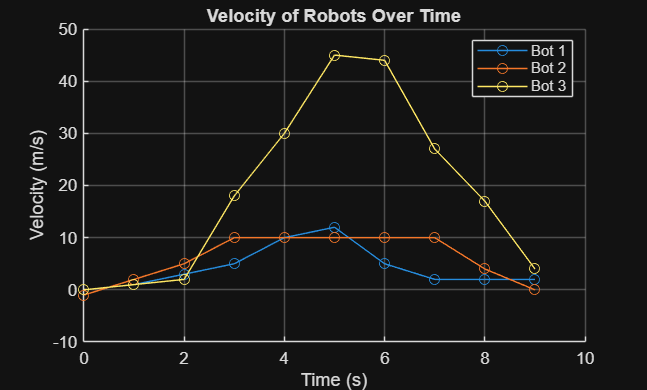

if any(Vval3<0) 
    disp('Reverse in bot 3')
end
% Plot the velocity data for each robot
figure;
hold on;
plot(Time, Vval1, '-o', 'DisplayName', 'Bot 1');
plot(Time, Vval2, '-o', 'DisplayName', 'Bot 2');
plot(Time, Vval3, '-o', 'DisplayName', 'Bot 3');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity of Robots Over Time');
legend ('Location','best');
grid on;
hold off;

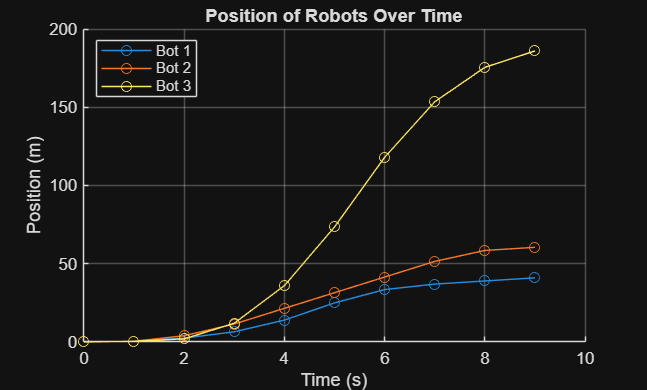

% Calculate acceleration for each dataset
%Diff finds the difference between adjacent values and ./ does division on
%each element
accel1 = diff(Vval1) ./ diff(Time);
accel2 = diff(Vval2) ./ diff(Time);
accel3 = diff(Vval3) ./ diff(Time);
% Integrate velocities to get position (assume initial position 0 for each)
%Integral is area under a curve, finding the integral of the velocity gives
%position.
pos1 = cumtrapz(Time, Vval1);
pos2 = cumtrapz(Time, Vval2);
pos3 = cumtrapz(Time, Vval3);

% Plot position vs time for each robot
figure;
hold on;
plot(Time, pos1, '-o', 'DisplayName', 'Bot 1');
plot(Time, pos2, '-o', 'DisplayName', 'Bot 2');
plot(Time, pos3, '-o', 'DisplayName', 'Bot 3');
xlabel('Time (s)');
ylabel('Position (m)');
title('Position of Robots Over Time');
legend ('Location','best');
grid on;
hold off;

%Ask for the threshold for the acceleration
askedthresh = inputdlg('What is the acceleration threshold?');
%Convert input to useable number
threshold = str2num(askedthresh{1})

threshold = 5

%Determine if the acceleration is beyond the threshold

if any(accel1 > threshold)
    disp('Acceleration exceeds threshold for Bot 1');
end
if any(accel2 >threshold) 
    disp ('Acceleration exceeds threshold for Bot 2')
end
if any (accel3>threshold)
    disp('Acceleration exceeds threshold for Bot 3')
end

Acceleration exceeds threshold for Bot 3
